（1）根据第九张PPT中表格所列的QA flag,首先开展对应波段反射率数据（Rrs_xxx）的质量控制；

clear;clc;
filename = "A2017050191000.L2_LAC_OC.nc";
% 查看nc文件信息
info = ncinfo(filename);
% 读取用于质控的flag
l2_flags = ncread(filename, 'geophysical_data/l2_flags');
% 需要用于判断质控的位置
bit_position = [0 1 3 4 5 8 9 12 14 15 16 19 21 22 25];
% 新建用于质控的矩阵
mask = zeros(size(l2_flags));
% 使用for循环，对多个bit位进行质控的筛选
for i = [1:length(bit_position)]
    % 获取该bit位的flag值
    b = bitget(l2_flags,bit_position(i) + 1);
    % 叠加flag
    mask = mask + double(b);
end
% 如果任何一个bit位有质量问题，反映到最后的mask上为该位置处的数值大于0.
% 把mask中大于0的数值置空。
mask(mask>0) = nan;
% 后续对数值读取使用isnan(mask)控制

% 使用NASA OC3M算法需要443, 488, 547波段的数值
Rrs_443 = ncread(filename, 'geophysical_data/Rrs_443');
Rrs_488 = ncread(filename, 'geophysical_data/Rrs_488');
Rrs_547 = ncread(filename, 'geophysical_data/Rrs_547');
% 对这些波段进行质控
Rrs_443(~isnan(mask)) = nan;
Rrs_488(~isnan(mask)) = nan;
Rrs_547(~isnan(mask)) = nan;

（2）将质量控制后的数据投影到标准经纬网格，像元空间分辨率0.01°

% 读取经纬度数据
lon = ncread(filename, 'navigation_data/longitude');
lat = ncread(filename, 'navigation_data/latitude');
% Convert geolocated data array to regular data grid
%[Z, E] = geoloc2grid(lat,lon,Rrs_443,0.5);

% 得到lat的最小值
minLat = min(lat,[],"all") - 5 * 0.1;
% 得到lon的最小值
minLon = min(lon,[],"all") - 5 * 0.1;
% 得到lat的最大值
maxLat = max(lat,[],"all") + 5 * 0.1;
% 得到lon的最大值
maxLon = max(lon,[],"all") + 5 * 0.1;
% 得到数据大小
rasterSize = size(lat);
% 建立空间几何校正映射数组R
R = georefcells(double([minLat maxLat]), double([minLon maxLon]), rasterSize);
% 经纬度转换为行列号
[xIntrinsic,yIntrinsic] = geographicToIntrinsic(R,lat,lon);


（3）基于Lake Nicaragua 矢量文件，裁剪出研究区数据（研究区外的数据mask为NaN）

area = shaperead('lake nicaragua2.shp');


（4）利用NASA OC3M算法，开展Lake Nicaragua湖区叶绿素浓度的计算

（5）将计算结果进行伪彩色显示, 使用jet颜色条即可

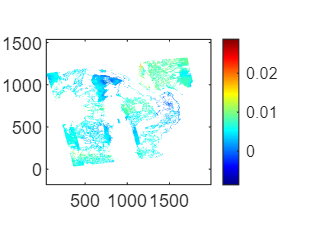

% 制图
pcolor(xIntrinsic, yIntrinsic, Rrs_443); 
shading flat; 
colormap(jet); 
colorbar; 
axis equal;

（6）将矢量文件叠加显示在结果图上